# Location Analysis

clear;
clc;

## Wild Type

### n=1

WT_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=1/results_from_time_0/location.dat";
[WT_1_LuminalPositions, WT_1_MyoepithelialPositions, WT_1_r, WT_1_r2] = CellPosition(WT_1);

### n=2

WT_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=2/results_from_time_0/location.dat";
[WT_2_LuminalPositions, WT_2_MyoepithelialPositions, WT_2_r, WT_2_r2] = CellPosition(WT_2);

### n=3

WT_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=3/results_from_time_0/location.dat";
[WT_3_LuminalPositions, WT_3_MyoepithelialPositions, WT_3_r, WT_3_r2] = CellPosition(WT_3);

### n=4

WT_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=4/results_from_time_0/location.dat";
[WT_4_LuminalPositions, WT_4_MyoepithelialPositions, WT_4_r, WT_4_r2] = CellPosition(WT_4);

### n=5

WT_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=5/results_from_time_0/location.dat";
[WT_5_LuminalPositions, WT_5_MyoepithelialPositions, WT_5_r, WT_5_r2] = CellPosition(WT_5);

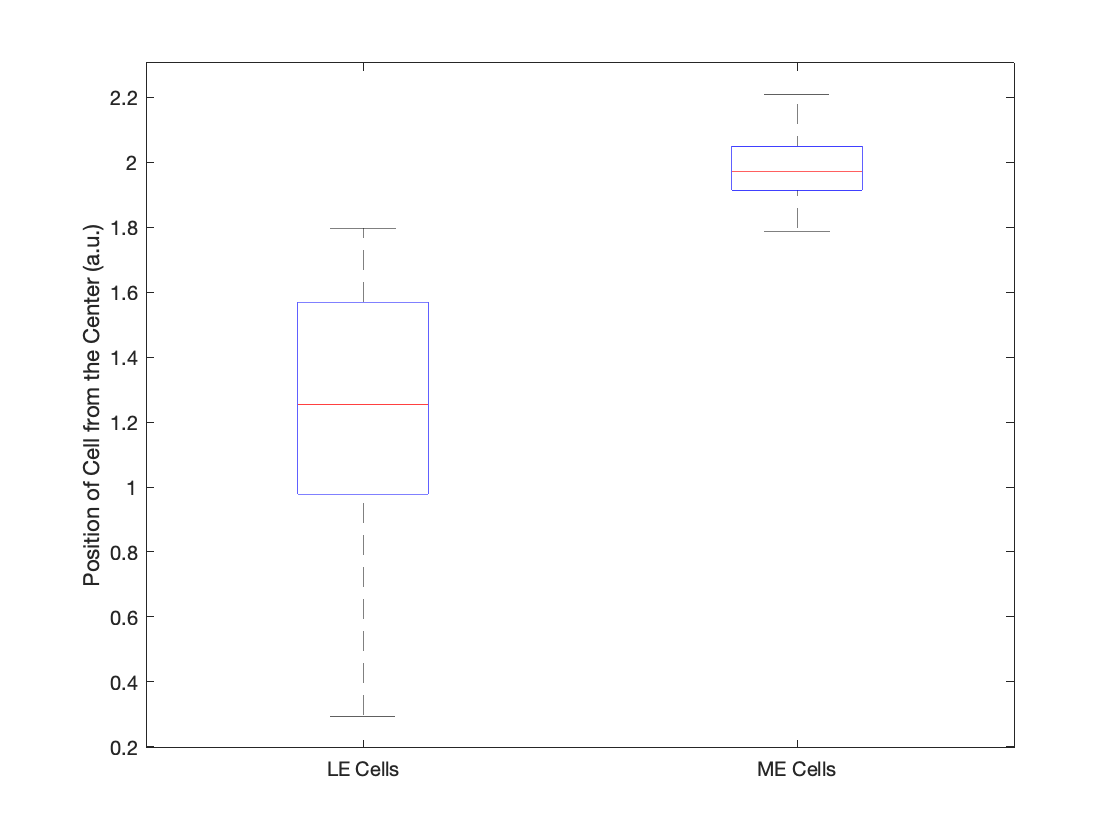

% Box plot final position of cells

figure 

luminal = WT_1_r(end,:);
myo = WT_1_r2(end,:);
g = [luminal myo];
C = [zeros(1,length(luminal)) ones(1,length(myo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition.pdf');

movefile('CellPosition.pdf', folder);

% combine data from all experiments
LEposition = cat(1,WT_1_r(end,:),WT_2_r(end,:),WT_3_r(end,:),WT_4_r(end,:),WT_5_r(end,:));
MEposition = cat(1,WT_1_r2(end,:),WT_2_r2(end,:),WT_3_r2(end,:),WT_4_r2(end,:),WT_5_r2(end,:));

%Calculate Mean
LEaverage = mean(LEposition,2);
MEaverage = mean(MEposition,2);

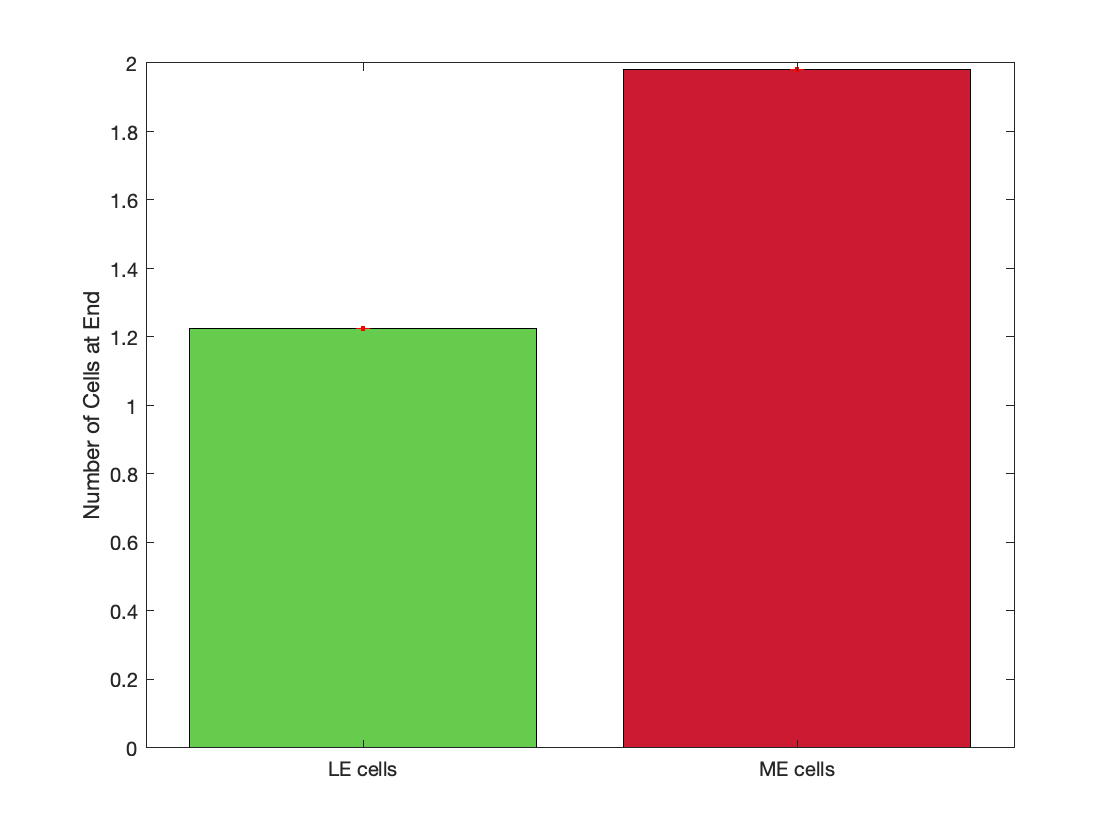

% plot average position of cells include data from all n=5 

%Calculate Mean and Standard Deviation
meanLE = mean(LEaverage);
meanME = mean(MEaverage);

y = cat(2,meanLE, meanME);

stdLE = std(LEaverage);
stdME = std(MEaverage);

error = cat(2,stdLE, stdME);

x=categorical({'LE cells', 'ME cells'});

b = bar(x,y);

%Make SD error bars 
hold on
errorbar(x,y, error, '.r')
hold off

ylabel('Number of Cells at End') 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

hold off

folder = '~/Desktop/';
exportgraphics(gca, 'AverageCellPosition.pdf');

movefile('AverageCellPosition.pdf', folder);